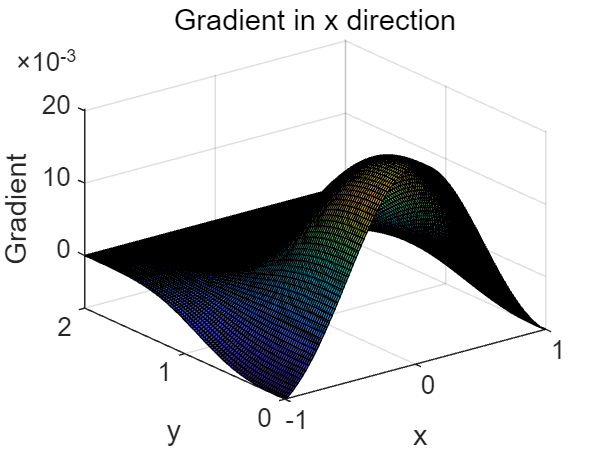

%题1
% 定义x和y的范围
x = linspace(-1, 1, 100);
y = linspace(0, 2, 100);
% 创建一个网格
[X, Y] = meshgrid(x, y);
% 计算z值
Z = X .* exp(-X.^2 - Y.^3);
% 计算梯度
[Gx, Gy] = gradient(Z);
% 绘制x方向的梯度
figure
surf(X, Y, Gx)
title('Gradient in x direction')
xlabel('x'),ylabel('y'),zlabel('Gradient')

%题2
% 2.1
f = @(x) (1/sqrt(2*pi))*exp(-x.^2/2);
result1 = integral(f, 0, 1)

result1 = 0.3413

% 2.2
fun=@(x)exp(2*x).*cos(x).^3;
result2 = integral(fun,0,2*pi)

result2 = 9.7054e+04

% 2.3
f = @(x) sqrt(2*x - x.^2);
result3 = integral(f, 0, 1)

result3 = 0.7854

% 2.4
f = @(x) (x.^3 + sin(x).^2).*cos(x).^2;
result4 = integral(f, -pi/2, pi/2)

result4 = 0.3927

% 2.5
f = @(x) x.*(1 - x.^4).^(3/2);
result5 = integral(f, 0, 1)

result5 = 0.2945

% 题3
t=linspace(0,2*pi,100);
x=2*cos(t);
y=3*sin(t);
dx=gradient(x,t);
dy=gradient(y,t);
f=sqrt(dx.^2+dy.^2);
perimeter = trapz(t,f)

perimeter = 15.8548